# Intro to EMG data for Smile vs Frown

#### Neurotechnology, Brains and Machines 2021

#### Sam Michalka 

I collected data while wearing 2 sets of EMG sensors on my face. Sometimes, I smiled, sometimes I frowned. Your goal is to determine which I was doing based on the EMG data from these two sensors. This notebook builds on what you've already learned about machine learning, but adds the additional complication of timeseries data, which requires feature extraction and selection.

Load the training data. (data here: [https://drive.google.com/file/d/1TuB3_2uWVChGtABvQnettvpUuSblhgpR/view?usp=sharing](https://drive.google.com/file/d/1TuB3_2uWVChGtABvQnettvpUuSblhgpR/view?usp=sharing) )

clear
load('EMGfrownsmileTrain.mat')
size(traindata)

ans =            2        1000         216


Using the size function, you can see that the data has 3 dimensions (channels x timepoints x trials).

The data for the zygomaticus major are channel 1, and the data for the corrugator supercilii are channel 2. In this experiment, I made a series of facial expressions. I chopped the data up into 216 trials or “epochs”. In each trial, I made a particular facial expression starting around the 0 millisecond mark (see *times_ms* for timepoints in ms, noting that the times start -500 ms before the facial expression). There are 1000 points in each trial, representing 1000 measurements (one every 4 ms… or what is called a 250 Hz sampling rate).

 The time_ms vector tells you what the time was at a particular point, measures in milliseconds. This value is relative to when I pressed a button to indicate my facial expression (right before making it). 

time_ms(500:505) % this corresponds to the second dimension in the train data

ans =         1496        1500        1504        1508        1512        1516


In Matlab, you can index a multidimensional array by typing in the values in each dimension. For example, if I want to see the data for channel 2, for some timepoints in the middle of my trials (500th time point to 505th), for the first 3 trials, I can use the code below:

traindata(2,500:505,1:3)

ans = 1×6×3 single array
ans(:,:,1) =

    0.7239    2.6680   -1.9270    2.8618    1.2177   -0.0174


ans(:,:,2) =

  162.8801  163.2348  163.3961  159.5294  157.6335  158.1934


ans(:,:,3) =

   -7.7952    2.4773    2.9582   -6.6735    0.7959    4.9260


Note that the size of this output array has one dimension that has no depth (the size in the first dimension is only 1).

size(traindata(2,500:505,1:3))

ans =      1     6     3


Some Matlab functions get angry when you try to feed them data with 3 dimensions, even if one of those dimensions is a singleton dimension. You can use the squeeze function to remove singleton dimensions.

squeeze(traindata(2,500:505,1:3))

ans = 6×3 single matrix
    0.7239  162.8801   -7.7952
    2.6680  163.2348    2.4773
   -1.9270  163.3961    2.9582
    2.8618  159.5294   -6.6735
    1.2177  157.6335    0.7959
   -0.0174  158.1934    4.9260


size(squeeze(traindata(2,500:505,1:3)))

ans =      6     3


## Plotting the time series

We know there are 216 trials in this data set, and each has a corresponding label in the variable *trainlabels*. This label tells you what expression I was attempting to make. These different labels are often referred to as different “conditions” of the experiment. Here’s a key:

F pressed: frown… I tried to look sad and pout a little

S pressed: smile… I smiled, just thinking about you learning to analyze this data… such joy

You can see how the trials are divided up by calling the summary function.

summary(trainlabels)

     F pressed      108 
     S pressed      108 


#### Exercise 1: Make separate plots for each condition (smiling, frowning) that show all of the trials at once. Using imagesc may be a good approach, or you can plot them as a bunch of lines. Be sure to label your axes. Do this separately for each channel. What do you observe?

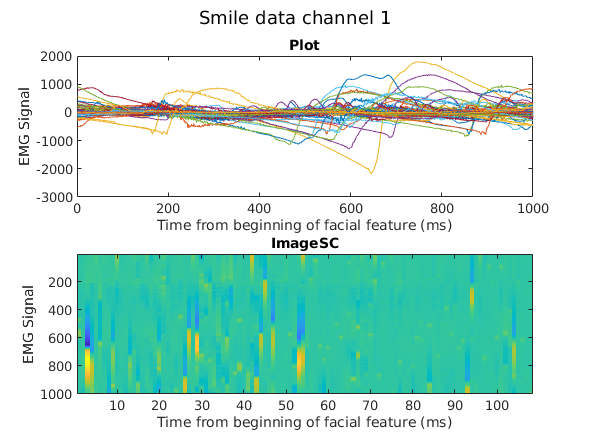

smile_traindata = traindata(:,:,trainlabels=="S pressed");
frown_traindata = traindata(:,:,trainlabels=="F pressed");

%smiling channel 1
figure()
sgtitle("Smile data channel 1")
subplot(2,1,1)
plot(squeeze(smile_traindata(1,:,:)))
title('Plot')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')
subplot(2,1,2)
imagesc(squeeze(smile_traindata(1,:,:)))
title('ImageSC')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')

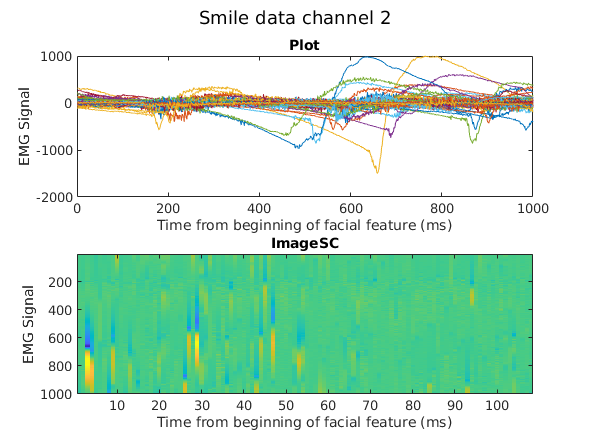


%smiling channel 2
figure()
sgtitle("Smile data channel 2")
subplot(2,1,1)
plot(squeeze(smile_traindata(2,:,:)))
title('Plot')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')
subplot(2,1,2)
imagesc(squeeze(smile_traindata(2,:,:)))
title('ImageSC')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')

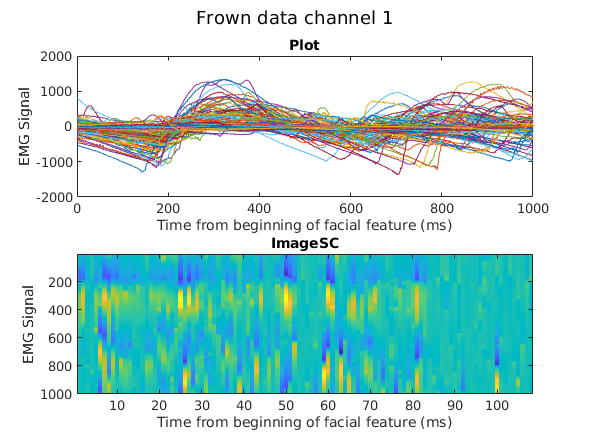


%frowning channel 1
figure()
sgtitle("Frown data channel 1")
subplot(2,1,1)
plot(squeeze(frown_traindata(1,:,:)))
title('Plot')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')
subplot(2,1,2)
imagesc(squeeze(frown_traindata(1,:,:)))
title('ImageSC')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')

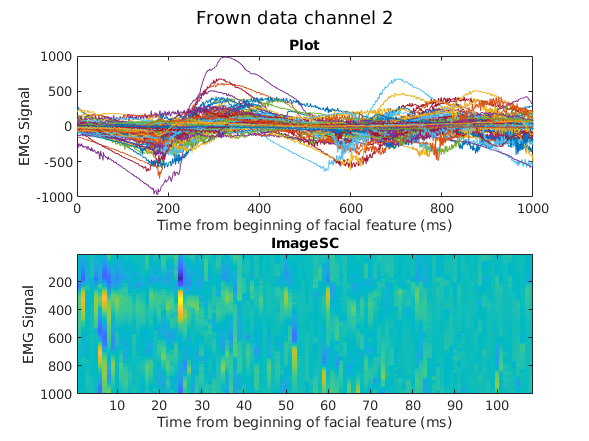


%frowning channel 2
figure()
sgtitle("Frown data channel 2")
subplot(2,1,1)
plot(squeeze(frown_traindata(2,:,:)))
title('Plot')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')
subplot(2,1,2)
imagesc(squeeze(frown_traindata(2,:,:)))
title('ImageSC')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')

#### Exercise 2: Calculate the mean time series (values over time) for the two conditions by showing them on the same plot with time in ms on the x-axis. Do this separately for each channel. What do you observe?

Optional challenge: Include separate lines to indicate 95% confidence intervals around each time course.

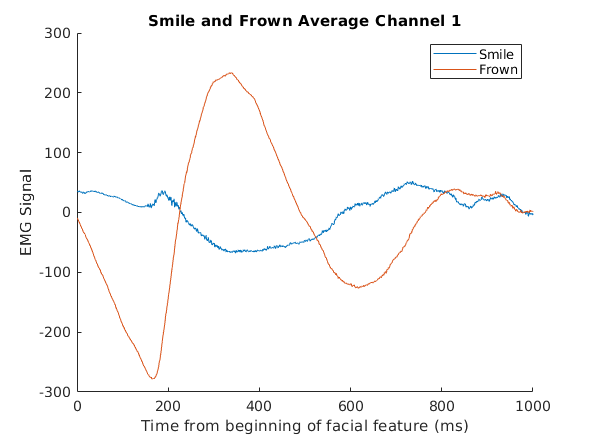

smile_avg_train = mean(smile_traindata, 3);
frown_avg_train = mean(frown_traindata, 3);

%channel 1
figure()
hold on
plot(smile_avg_train(1,:))
plot(frown_avg_train(1,:))
title('Smile and Frown Average Channel 1')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')
legend('Smile', 'Frown')
hold off

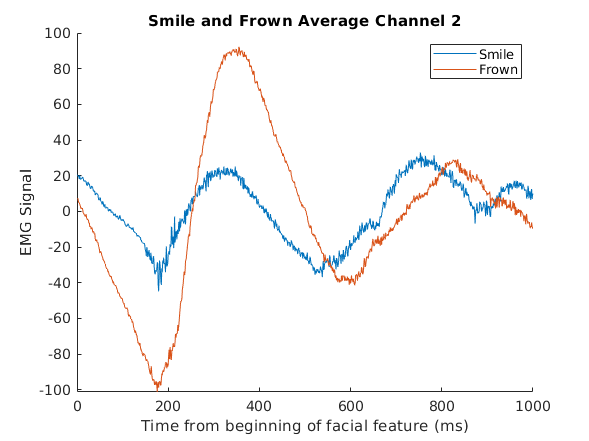


%channel 2
figure()
hold on
plot(smile_avg_train(2,:))
plot(frown_avg_train(2,:))
title('Smile and Frown Average Channel 2')
xlabel('Time from beginning of facial feature (ms)')
ylabel('EMG Signal')
legend('Smile', 'Frown')
hold off

## Thinking about classification of time series data

Our goal is to classify whether a hilarious person is smiling or frowning, based on the EMG data from the two sensors. This builds on the previous machine learning assignments, but now we are starting with data that is a bunch of values over time. In order to get interesting features for our classifier, we want to do some calculations to pull out what might be informative in this data, instead of plugging in all of the raw data. 

#### Exercise 3: For the classification methods that we've looked at so far, why would just plugging in all of the raw data as features not be a great plan?

The classification methods we've looked at so far look at specific (singular) values for each classification, while this has a timeseries of data for each classification.

There are other machine learning methods that are appropriate for taking raw time series data in as inputs. We won't cover them in the main portion of this course, but if you are already feeling confident in machine learning, you might enjoy challenging yourself by investigating these methods. 

Instead of putting in 1000 x 2 EMG time points into our classifier for each trial, we need to find a way to extract and select appropriate features for our analysis. For example, we might want to look at the maximum value in our signal during the time period (epoch/trial) of interest. I can use the max() function to find the maximum value of the signal for each channel and trial, and store this in the array maxvaluesperchantrial

maxvaluesperchantrial = max(traindata,[],2);
size(maxvaluesperchantrial)

ans =      2     1   216


Notice that this has a singleton dimension, so I'll need to use the squeeze function to remove this. I am going to store my potential features in a table called trainfeatures to keep things organized. Notice the dimensions of this table and that I labeled the feature variables so that I can keep track of them. 

trainfeatures= array2table(squeeze(maxvaluesperchantrial)','VariableNames',{'Ch1_max','Ch2_max'})

trainfeatures = 216×2 table
    Ch1_max    Ch2_max
    _______    _______

    508.64     45.415 
    393.38     271.39 
    216.92     88.593 
    1792.5     1005.4 
    806.49        616 
    806.49        616 
    104.46     68.952 
    278.79     57.959 
    239.48     55.865 
    477.43     90.613 
    128.07     104.55 
    175.57     133.74 
    540.44     397.45 
    540.44     397.45 
    974.89     678.65 
    974.89     678.65 


#### Exercise 4: Make a scatter plot that shows the maximum value for each channel with colors representing the two facial expressions. Describe what you observe and explain how well you think these two feature would be able to classify smile vs frown.

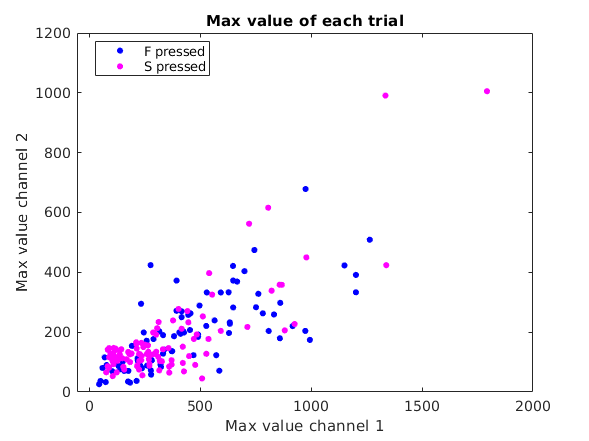

gscatter(table2array(trainfeatures(:,1)), table2array(trainfeatures(:,2)), trainlabels, "bm")
title("Max value of each trial")
xlabel("Max value channel 1")
ylabel("Max value channel 2")

From  looking at this scatter plot, I don't think these two features would be able to classify smile v frown very well. There doesn't seem to be a clear distinction or line you can draw between the smile trials and the frown trials.

## Quick classification using code

Now we can run a quick support vector machine classification in code.  (If you are using an older version of Matlab, you may need to convert the labels to a table.)

% This is the code that sets up the SVM classifier
trainedClassifier = fitcsvm(trainfeatures, ...
    trainlabels, ...
    'KernelFunction', 'Linear', ...
    'Standardize',false...  
     );  %

The next part sets up cross-validation. Look this up (this is commonly used in machine learning).

% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart = cvpartition(trainlabels,'KFold',kval); % k-fold stratified cross validation
partitionedModel = crossval(trainedClassifier,'CVPartition',cpart);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
     
% Cross validation output
validationAccuracy = sum(validationPredictions==trainlabels)./length(trainlabels);
%validationAccuracy = 1 - kfoldLoss(partitionedModel); %This is another way
%to find the accuracy. If you want a challenge, you can look up loss
%functions in machine learning

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 56.48%


Okay, so that's probably not an amazing classification accuracy. I think we can do better. The rest of the analysis portion of your assignment to improve upon this (don't forget that there's one more part in the main assignment too).

#### Exercise 5 (more of a full workout): Improve this classifier and share your best method and results here: [https://docs.google.com/spreadsheets/d/18qglL0x-WDohqSMgy8-dADwvpIT5083NRGIYw_Zt__U/edit?usp=sharing](https://docs.google.com/spreadsheets/d/18qglL0x-WDohqSMgy8-dADwvpIT5083NRGIYw_Zt__U/edit?usp=sharing)   (You are welcome to share more than one).

This is a big task, so please read below for some tips about how to approach this. 

clear
load('EMGfrownsmileTrain.mat')

%pre-process: remove average from baseline
%calcualte average before 0ms for both channels
avg_prior = mean(traindata(:,:,time_ms<0), 3);
avg_prior = mean(avg_prior, 2);
traindata_pro = traindata - avg_prior; %subtract average form data

%narrow the time window: only look at data after 0ms
traindata_pro = traindata_pro(:, time_ms >= 0, :);

%calcualte features
train_max_pro = max(traindata_pro,[],2);
train_max_pro = squeeze(train_max_pro)';
train_rms = rms(traindata_pro, 2);
train_rms = squeeze(train_rms)';
train_avg = mean(traindata_pro, 2);
train_avg = squeeze(train_avg)';

features = [train_rms]; %just rms gave best accuracy, so just use rms

trainedClassifierRms = fitcsvm(features, ...
    trainlabels, ...
    'KernelFunction', 'gaussian', ...
    'Standardize',true...  
     );  

% k-fold cross validation
kval = 5; %Choose number of folds. You can also just set this manually.
cpart = cvpartition(trainlabels,'KFold',kval); % k-fold stratified cross validation
partitionedModel = crossval(trainedClassifierRms,'CVPartition',cpart);

% Make predictions of the crossfold validation predicted based on the traindata
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);
     
% Cross validation output
validationAccuracy = sum(validationPredictions==trainlabels)./length(trainlabels);

fprintf('\nValidation accuracy = %.2f%%\n', validationAccuracy*100);


Validation accuracy = 68.06%


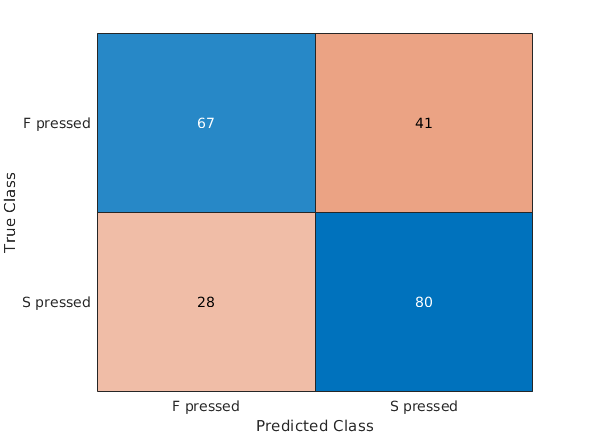

confusion_mat =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties



confusion_mat = confusionchart(trainlabels, validationPredictions)

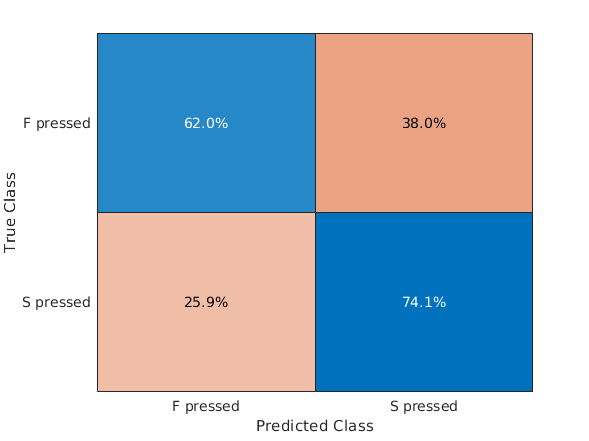

confusion_mat_norm =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 categorical]

  Show all properties


confusion_mat_norm = confusionchart(trainlabels, validationPredictions, 'Normalization','row-normalized')

#### Exercise 6 (optional challenge): Manipulate your classifier in some way (adding different features, looking at different time windows, or changing the parameters for whatever algorithm you choose). Do this in a systematic way and record how this affects some measure of algorithm goodness (accuracy, area under the ROC curve, F-score). Plot this relationship. If you want to get really fancy, you can do this for two different manipulations (this is sometimes called sweeping the paramer space).

## Hot tips for improving the EMG classifier    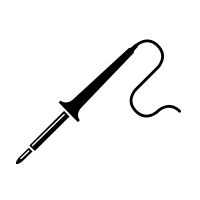

There are several strategies that you might take to improve the classifier:

- Add additional preprocessing

- Narrow the time window

- Calculate additional features

- Try a different algorithm and/or tweak the algorithm parameters.

These are numbered based on the order that you apply them to your data. However, they are essentially in reverse order of importance (calculating more/different features is the most important). See more info about each of these strategies below.

### 1. Add additional preprocessing

These data have already mostly been preprocessed for you using:

- a high pass filter at 0.5 Hz to remove drift

- a notch filter from 56 to 64 Hz to remove electrical noise at 60 Hz (this would be 50 Hz, if I were in Europe)

- epoching to chop the data up into 1000 timepoints or 4 seconds sampled at 250 samples per second (250 Hz sampling rate)

However, there are other preprocessing that is sometimes used for EMG data. I suggest only doing one of these at any given time: 

- remove the average signal from each trial (centering each trial around zero).

- filter the data more to remove noise

- remove the average signal from the baseline (timepoints prior to the facial expression, which happens around 0 ms)

You might enjoy these Matlab functions: mean(), highpass(), lowpass(), bandpass()

### 2. Narrow the time window

Right now, the data include a pretty large time window, include data from before I even started to make the facial expression. You can experiment with different windows. It might be helpful to go back and look at your time series plots from the beginning of this notebook to think about what time window would be appropriate.

 We might choose to use only a subset of this epoch, especially since it might not make sense to extract information from before the event happened (at 0 ms). Here's some code that might be helpful

timewindowforfeatures = [-100 1000]; %start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowepochidx = (find(time_ms>=timewindowforfeatures(1),1)):(find(time_ms>=timewindowforfeatures(2),1));
windoweddata = traindata(:,timewindowepochidx,:);
size(traindata)

ans =            2        1000         216


size(windoweddata)

ans =      2   276   216


### 3. Calculate additional features 

Here are some ideas for features to add (you can look these up in online resources, including some papers linked below):

- mean of the absolute value of the signal

- root mean square (rms) 

- the variance of the signal

- integrated EMG (iEMG)

- simple squared integral (SSI)

- bandpower in different frequency bands (e.g., 64 to 110 Hz)

- other ideas that you come up with, you might look back at the plots to think about how the smile and frown signals look different.

***There are also existing Matlab functions for many of these (or parts of them), so you don't need to code the whole formula from scratch.***

Here are a couple papers with some info, but you can also find your own. 

[Mithbavkar, Shraddha Atul, and Milind Shantilal Shah. "Recognition of Emotion Through Facial Expressions Using EMG Signal." 2019 International Conference on Nascent Technologies in Engineering (ICNTE). IEEE, 2019.](https://drive.google.com/file/d/1z2df6YGj-S1I4xbYPOcqUqHkP70LQFSM/view?usp=sharing)

Paper you looked at already in this assignment: [https://www.ncbi.nlm.nih.gov/pmc/articles/PMC1455479/](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC1455479/))

### 4. Try a different algorithm and/or tweak the algorithm parameters.

You can look up the different parameters you can put into the fitcsvm function, these include things like: 'OutlierFraction',0.10,...

Or you might want to look up other classifiers besides SVM to use here. Matlab has lots of options, which have different parameters, but tend to take in the same form of predictors and response variables.

[https://www.mathworks.com/help/stats/classification.html](https://www.mathworks.com/help/stats/classification.html)